## Multiple MRI to Multiple PLI Registration (with middle MRI OC slice)

Description:

- This code registers 3 MR OC images to 3 corresponding PLI images using cpselect.

- MRI OC images were previosly transformed with mipav to make them flat to the imaging plane

- This code takes one middle slice from the OC MRI for each sample

- Then the MRI undergoes landmark registration into PLI space for each sample

- Outputs all images as .pngs to "resultsDir"

Author: Rhea Carlson

Date: 12/1/2023

clear
clc
close all

Step 1: Get filepaths for each image (FA, DT vector...) across three samples

MAINDIR="/xdisk/hutchinsone/rheacarlson/Workspace/PLI_hist/DATA";
MRI_dir=fullfile(MAINDIR,"data/MRI/FT_optic_chiasm_final/blip_up_proc/transform_images");
sample_names=["F001","F002","F003"];
MR_types=["blip_up_DMC_L0_DT_FA_transform.nii","blip_up_DMC_mapmri_PA_transform.nii","DTvector0_transform.nii","DTvector1_transform.nii","DTvector2_transform.nii"];
PLIDir=fullfile(MAINDIR,"data","PLI");
PLI_ref="mask_reference.png";

%%%%%% choose to run thin (0) or thick (1) %%%%%%
run_thick_or_thin=0;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if run_thick_or_thin==0
    % run thin
    PLI_crossing = ["Crossing_Sample1_thin","Crossing_Sample2_thin","Crossing_Sample3_thin"];
    resultsDir=fullfile(MAINDIR,"results","registration","thin");
elseif run_thick_or_thin==1
    % run thick
    PLI_crossing = ["Crossing_Sample1_thick","Crossing_Sample2_thick", "Crossing_Sample3_thick"];
    PLI_ref="mask_reference.png";
    resultsDir=fullfile(MAINDIR,"results","registration","thick");
end

MRimageDirs=strings([1,0]);
for i=1:length(sample_names)
    for j=1:length(MR_types)
        temp=fullfile(MRI_dir,sample_names(i),MR_types(j));
        MRimageDirs=[MRimageDirs,temp];
    end
end

PLI_filenames_cr=string(length(PLI_crossing));
for i=1:length(sample_names)
   PLI_filenames_cr(i)=fullfile(PLIDir,PLI_crossing(i),PLI_ref);
end

PLI_filenames=PLI_filenames_cr; 
PLI_names=PLI_crossing;   


Step 2: Prep Data for landmark registration

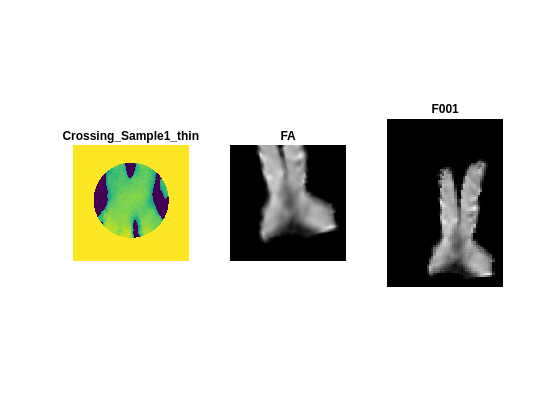

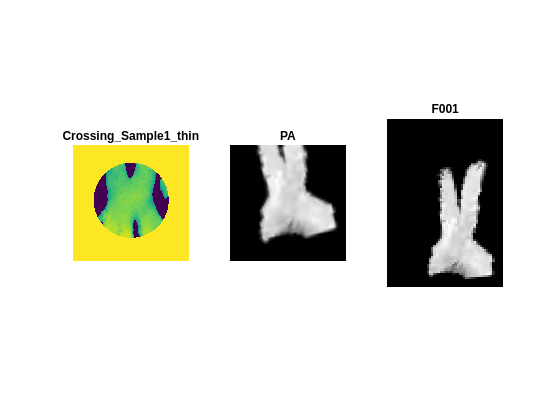

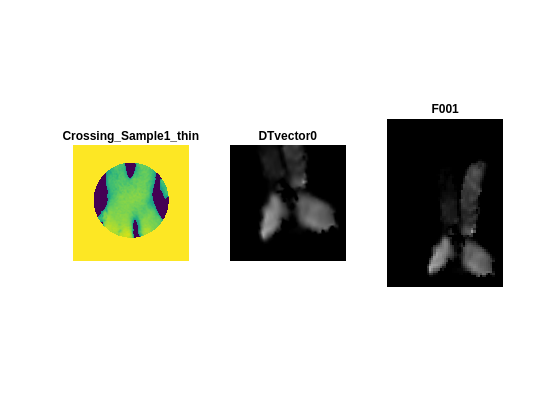

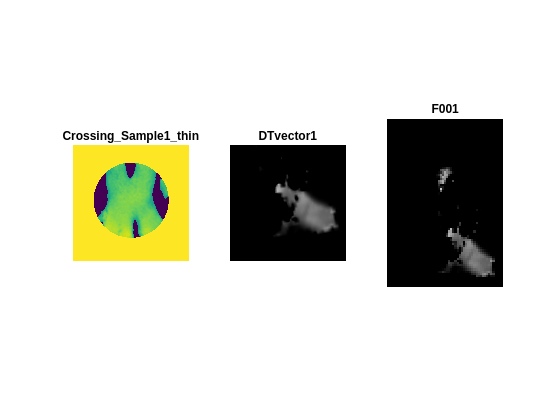

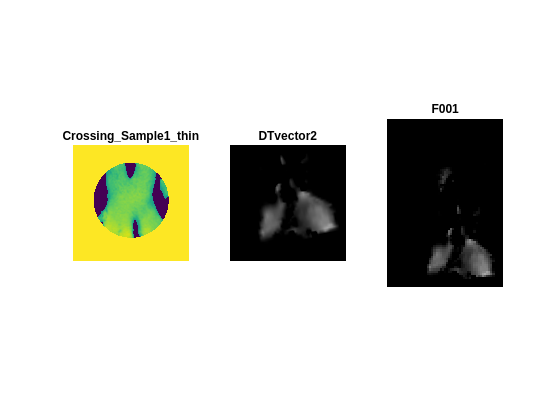

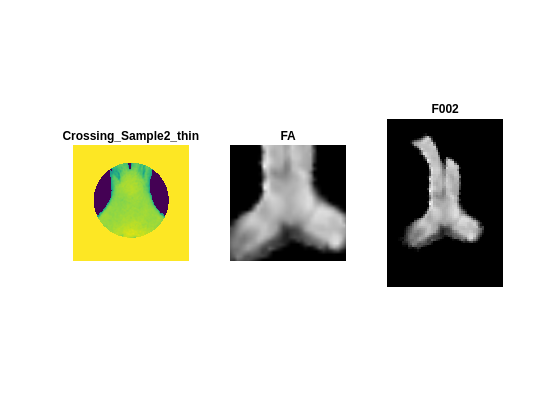

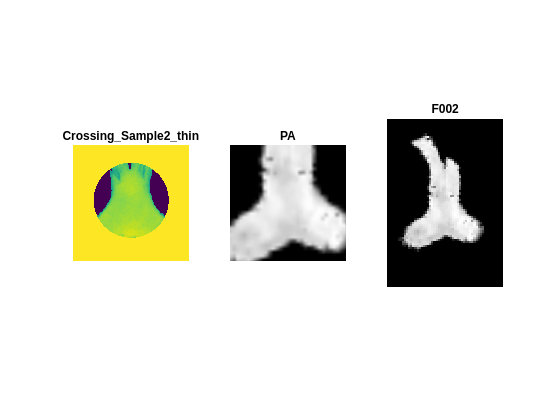

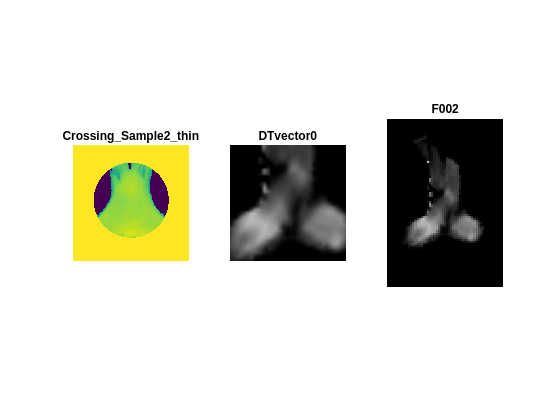

f1=1;
for i=1:length(MRimageDirs)
    % get file and read in nifti
    my_file=MRimageDirs{i};
    nii=load_nii(my_file);
    image_data = nii.img;
    
    % select slices
    if contains(my_file,"F001")
        slice_num=14; %from itksnap z
    elseif contains(my_file,"F002")
        slice_num=43;
    elseif contains(my_file,"F003")
        slice_num=49;
    end

    % get slice and set it as the moving frame for registration    
    slice=image_data(:,:,slice_num);
    slice=rot90(slice,3);
    moving = squeeze(slice);

    
    %label image type - for saving out registered image
    if contains(my_file, 'FA_transform.nii')            
        image_name = 'FA';
        fixed = imread(PLI_filenames{f1});
        [movingPoints1,fixedPoints1]=cpselect(moving,fixed,'Wait',true); % only cpselect for FA!
    elseif contains(my_file, 'PA_transform.nii')
        image_name = 'PA';       
    elseif contains(my_file, 'DTvector0')
        image_name = 'DTvector0';       
    elseif contains(my_file, 'DTvector1')
        image_name = 'DTvector1';     
    elseif contains(my_file, 'DTvector2')
        image_name = 'DTvector2'; 
    else
        fprintf('image type not specified')
        fprintf(my_file)
        image_name = 'error';
    end

    txfm1=fitgeotrans(movingPoints1,fixedPoints1,'NonreflectiveSimilarity');
    final=imwarp(moving,txfm1,'OutputView',imref2d(size(fixed)));

  
    % display images 
    figure;
    subplot(1,3,1), imshow(fixed);title(PLI_names(f1),'Interpreter', 'none');
    subplot(1,3,2), imshow(final);title(image_name,'Interpreter', 'none');  
    subplot(1,3,3), imshow(moving);title(sample_names(f1),'Interpreter', 'none');   

    resultspath = fullfile(resultsDir, strcat(image_name,"_",PLI_names(f1),".png")); 
    imwrite(final, resultspath)
    
    resultspath2 = fullfile(resultsDir, strcat(image_name,"_",sample_names(f1),'_avg-z.png'));
    imwrite(moving, resultspath2)
    
    if contains(my_file, 'DTvector2_transform.nii')
        f1=f1+1;
    end

        
end